clear all;
clc;
close all;
disp('Iris Eting 209027333')

Iris Eting 209027333


disp('Nadav Orenstein 312349509')

Nadav Orenstein 312349509


## 1 Edge Detection

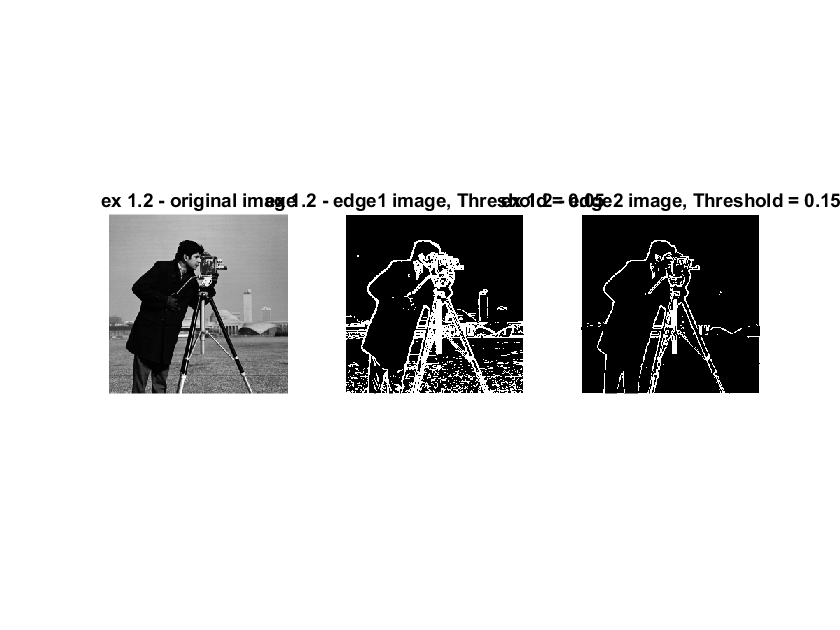

%%%%% 1 Edge Detection %%%%%%%
%1.1 Reading the Image
cameraman = imread_normalized_1("cameraman.tif");

%1.2 Prewitt Edge Detector
edge1 = dip_prewitt_edge(cameraman,0.05);
edge2 = dip_prewitt_edge(cameraman,0.15);

%% Display
fig = figure();
subplot(1,3,1);
imshow(cameraman);
title('ex 1.2 - original image');
subplot(1,3,2);
imshow(edge1);
title('ex 1.2 - edge1 image, Threshold = 0.05');
subplot(1,3,3);
imshow(edge2);
title('ex 1.2 - edge2 image, Threshold = 0.15');
saveas(fig,'ex 1.2.jpeg');

## 1.3 Canny Edge Detector

% 1.3 Canny Edge Detector
fig = figure();
subplot(1,2,1);
edge(cameraman,'canny');
title('Default canny');
subplot(1,2,2);
edge(cameraman,'canny',[0.2,0.5],1);
title('Canny with threshold=[0.2,0.5] and \sigma=1')
saveas(fig,'ex 1.3.2.jpeg');

## 2 Hough Transform

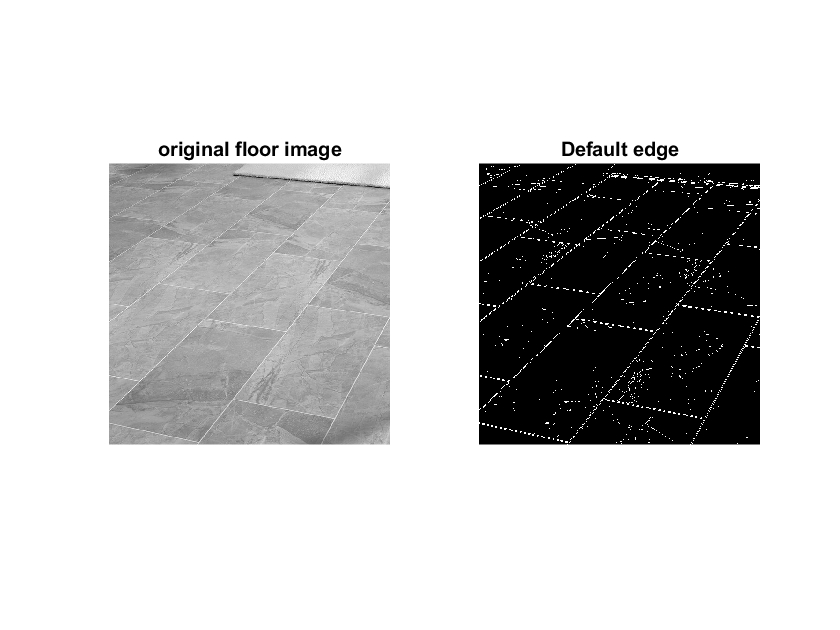

floor = imread_normalized("floor.jpg");
[BW,TH]=edge(floor);
% Display
fig = figure();
subplot(1,2,1);
imshow(floor);
title('original floor image');
subplot(1,2,2);
imshow(BW);
title('Default edge');
saveas(fig,'ex 2.1.b.jpeg');

TH

TH = 0.0565

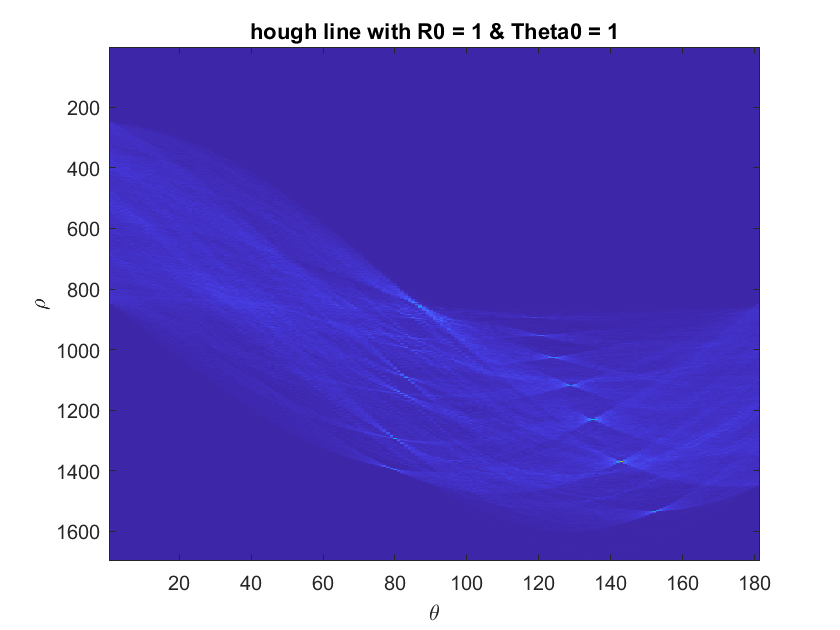


%%% 2.1.c
hough_matrix_1 = dip_hough_lines(BW, 1, 1);

hough_matrix_2 = dip_hough_lines(BW, 5, 4);

figure;  imagesc(hough_matrix_1); title("hough line with R0 = 1 & Theta0 = 1");
xlabel('\theta');
ylabel('\rho');

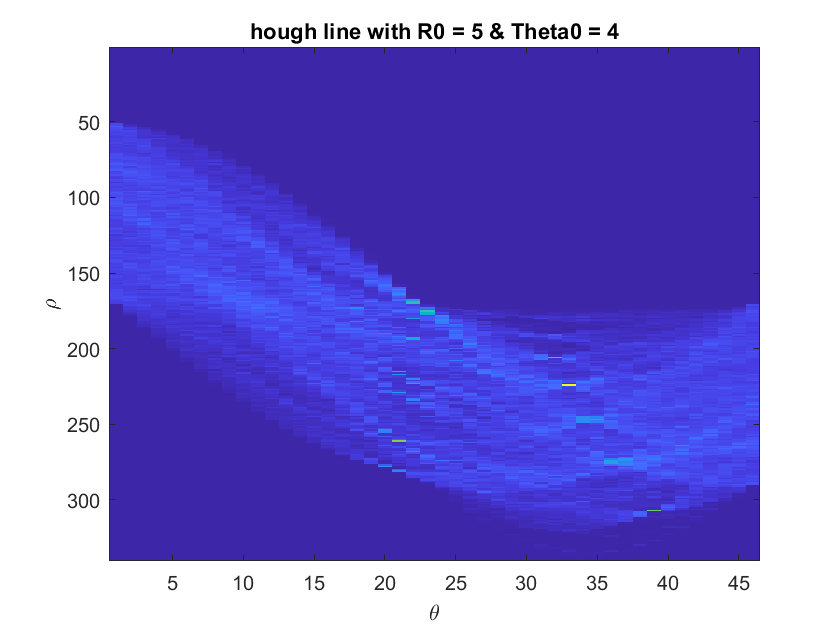

figure; imagesc(hough_matrix_2); title("hough line with R0 = 5 & Theta0 = 4");
xlabel('\theta');
ylabel('\rho');

## Using imshow(M,[]) did work but less visible for us that's why we used imgsec

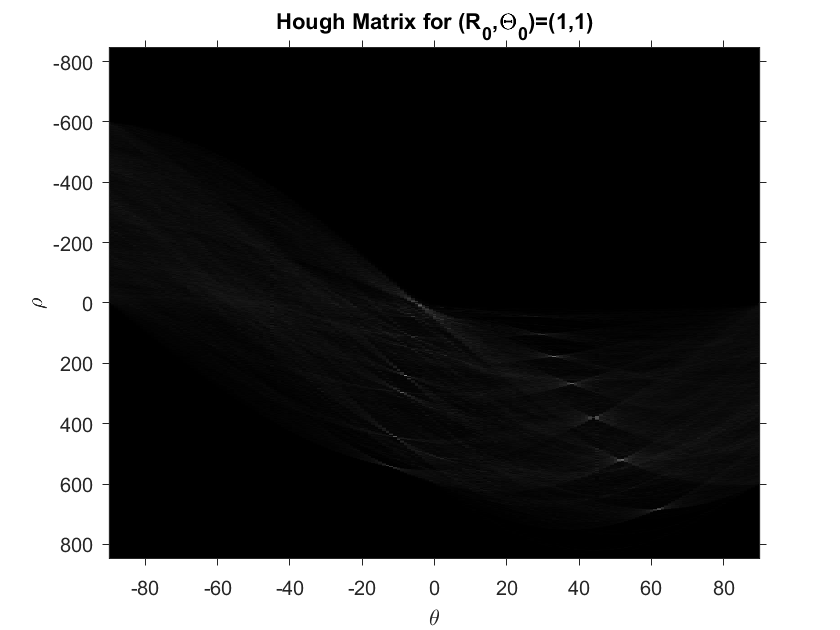

%
[M,N]=size(BW);
R1=fix(-sqrt(M^2+N^2):1:sqrt(M^2+N^2));
theta1=fix(-90:1:90);
figure;
imshow(hough_matrix_1,[],'XData',theta1,'YData',R1,'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal;
axis([-90 90 -sqrt(M^2+N^2) sqrt(M^2+N^2)])
title('Hough Matrix for (R_0,\Theta_0)=(1,1)');

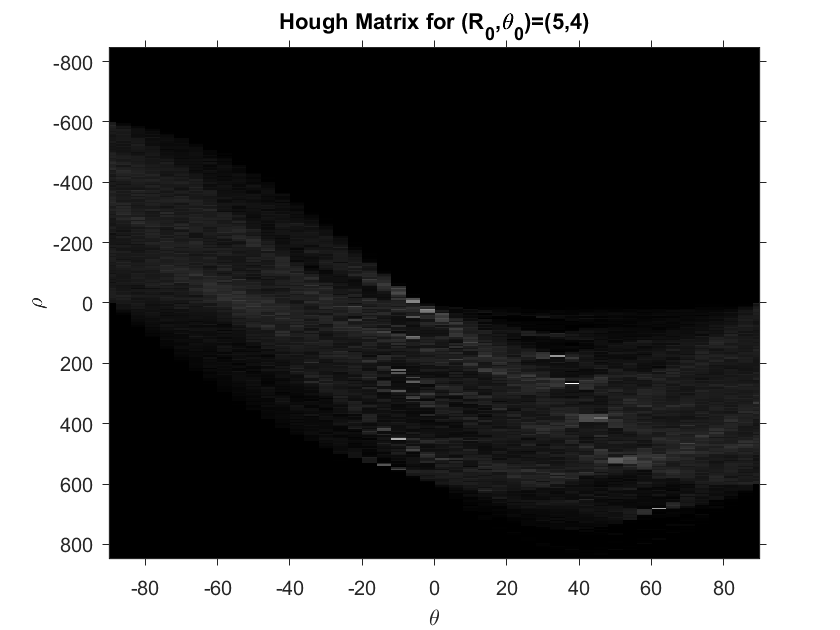

figure;
R5=-sqrt(M^2+N^2):5:sqrt(M^2+N^2);
theta4=-90:4:90;
imshow(hough_matrix_2,[],'XData',theta4,'YData',R5,'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal;
axis([-90 90 -sqrt(M^2+N^2) sqrt(M^2+N^2)])
title('Hough Matrix for (R_0,\theta_0)=(5,4)');

disp("hi")

hi


%

disp("hi nadav")

hi
